# **NoteBook For (1+1)D Split Operator Algorithm**

**By Ke Lin, Zhiyuan College, SJTU **

**Email: kelin7196@gmail.com**

**At Harvard University, 23 July, 2023**

**-----------------------------------------------------------------------------------------------------------------------------------**

**Note: In each section, there is a button labeled by "Run", You can run the coresponding section by clicking it. Feel free to try it for fun by clicking!**

**-----------------------------------------------------------------------------------------------------------------------------------**

## **Part0: Basic Principle Behind**

The Split-Operator Method (also called the Split-Step Method) is one of the simplest and fastest methods to numerically solve the Schrödinger Equation and is widely used throughout modern quantum research in the area, in particular when dealing with the Non-linear Schrödinger Equation (NLSE):


$$i \hbar \frac{\partial \Psi(\mathbf{r}, t)}{\partial t}=\left[-\frac{\hbar^2}{2 m} \nabla^2+V(\mathbf{r})+g|\Psi(\mathbf{r}, t)|^2\right] \Psi(\mathbf{r}, t)$$


where $\Psi(\mathbf{r}, t)$ is a quantum wave package with spatial and time dependence, $\nabla^2$ is a Laplacian and $V(\mathbf{r})$ is a potential of some sort. In this case, we also add an nonlinear term  $g|\Psi(\mathbf{r}, t)|^2$ where $g$ is the coefficient of it. This is the system I studied for most of my Undergrad reseacrh. It is also wildly used in Condense Matter Physics and AMO physics. We won't state why it can be used to characterize the propagation of light beam, it is beyond this Notebook. For more information, please refer to my another note <From Maxwell Equation to Schrodinger Equation: Analogy between Condense Matter Physics and Optics> in [GitHub](https://github.com/KeLin666).

We can seperate the Hamiltonian operator into two parts: Potential Energy Operator and Kinetic Energy Operator: 

$\hat{H_k}=-\frac{\hbar^2}{2 m} \nabla^2$ and  $\hat{H_r}=V(\mathbf{r})+g|\Psi(\mathbf{r}, t)|^2$

(note: here we regard nonlinear term as the equivalent potential energy)

Thus, we can get a general solution to our quantum system:


$$\Psi(\mathbf{r}, t+d t)=\left[e^{-\frac{i \hat{H} d t}{h}}\right] \Psi(\mathbf{r}, t)=\left[e^{-\frac{i\left(\hat{H}_r+\hat{H}_k\right) d t}{h}}\right] \Psi(\mathbf{r}, t)$$


Assume we are simulating our system by a series of small timesteps ($dt$), we can perform similar splitting by using the Baker-Campbell-Housdorff formula:


$$\Psi(\mathbf{r}, t+d t)=\left[e^{-\frac{i \hat{H} r d t}{h}} e^{-\frac{i \hat{H}_k d t}{h}} e^{-\frac{\left[i \hat{H} r, i \hat{H}_k\right] d t^2}{2}}\right] \Psi(\mathbf{r}, t)$$


This accrues a small amount of error ($dt^2$) related to the commutation of the real and momentum-space components of the Hamiltonian. This is a relatively large error and that's not okay. In order to change the $dt^2$ error to $dt^3
$, we can split the system by performing a half-step in position space before doing a full-step in momentum space, through a process called *Strang Splitting* like so:


$$\Psi(\mathbf{r}, t+d t)=\left[e^{-\frac{i \hat{H} r d t}{2 h}} e^{-\frac{i \hat{H}_{k d t}}{\hbar}} e^{-\frac{i \hat{H} r d t}{2 h}}\right] \Psi(\mathbf{r}, t)+\mathcal{O}\left(d t^3\right)$$


We can then address each part of this solution in chunks, first in position space, then in momentum space, then in position space again by using Fourier Transforms. Which looks something like this:


$$\Psi(r, t+d t)=\left[\hat{U}_r\left(\frac{d t}{2}\right) \mathcal{F}^{-1}\left[\hat{U}_k(d t) \mathcal{F}\left[\hat{U}_r\left(\frac{d t}{2}\right) \Psi(\mathbf{r}, t)\right]\right]\right]+\mathcal{O}\left(d t^3\right)$$


where $\hat{U}_r=e^{-\frac{i \hat{H} r d t}{h}}$ , $\hat{U}_k=e^{-\frac{i \hat{H}_k k^{d t}}{h}}$. Here's a flowchart of what we are looking for every timestep:

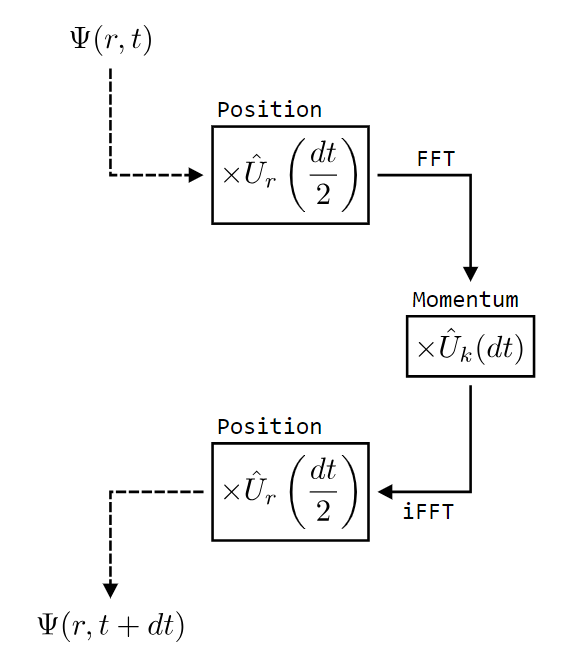

Fig01: Flowchart of split operator method

## **Part1: First Glimpse on the codes**

  % By clicking, you can propagating a plane wave in free space

In this section, we list codes for (1+1)D SSFFT, along with a step-by-step explanation. 

It can be seperated into Six parts:

- Set up: Assign values to parameters, including imaginary unit and grid.

- Initial condition: Initial wave function for light, e.x. Plane wave condition, Gaussian wave condition.

- Potential: Refractive index of space in AMO, or potential in Condense Matter Physics.

- Linear-Factor: Coefficient in K-Space when do propagation after FFT.

- Propagation: Loop for propagation.

- Visualization: Plot the result after propagation using imagesc.

Let's look it step by step. The first part is "set up". Here, the "ii" refers to the imaginary unit, and we have a grid with x ranging from -50 to 50 and z ranging from 0 to 100. We use the "meshgrid" function to create a 2D grid by setting the parameters in the x and z directions.


clear;clc;format long

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%% set up %%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

ii=sqrt(-1);
N=128;xmax=50;dx=(2*xmax)/(N-1);x=[-xmax:dx:xmax];
dz=0.1;zmax=50;NUM=zmax/dz+1;z=[0:dz:zmax];
[X,Z]=meshgrid(x,z);


Good job! Lets step forward to the part 2: initial condition. Here we use Gaussian wave fucntion as an example. By setting the amplitude and HWFM of the Gaussian wave, you are able to see how the initial wave looks like. Please vary the parameters and try to plot it!

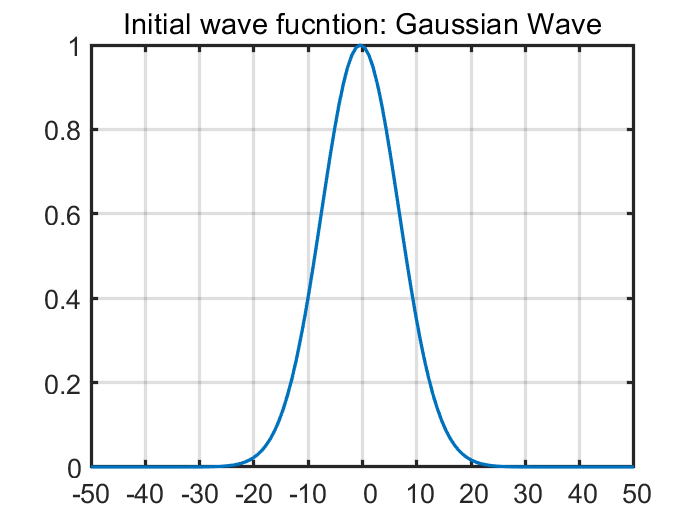

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%% Initial Conditions-1：Gaussian wave %%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

y=zeros(1,N);
A=1;sigma=0.1;

for i=1:N
    y(i)=A*exp(-(i-N/2)^2/N/N/sigma^2);
end

figure()
plot(y,'LineWidth',2)
title('Initial wave fucntion: Gaussian Wave')
xlim([1,N])
xTicks = linspace(-50, 50, 11);  % Generate 11 evenly spaced tick values within the range -50 to 50.
xTickLabels = cellstr(num2str(xTicks'));  % Convert tick values to a cell array of strings.
set(gca, 'XTick', linspace(1, 128, 11));  % Set Y-axis tick positions.
set(gca, 'XTickLabel', xTickLabels);  % Set Y-axis tick labels.
grid on
set(gca,'FontSize',16,'LineWidth',2)

Up to this point, the only term we do not set is the potential, or the refractive index in the space. Let's go into it. Here we provide a free space potential, that is, $n=1$ in air. 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%% Free space potential %%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

V=1*ones(NUM,N);


Now, we come into the most difficult part of our codes: Linear factor. You need to know the value of a parameter FACTOR that depends on the wavevector $k
$. It comes from Fourier Transform of the operator $\nabla^2$. Quick review, the Fourier transform of the Laplacian operator is given by $-k^2$, where $k
$ represents the wavevector. If we set

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%% LINEAR_FACTOR in spectrum space %%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for i=1:N
    if (i<=N/2+1)
        FX(i)=((i-1)/(N*dx))^2;
    else
        FX(i)=((i-1-N)/(N*dx))^2;
    end
end

FACTOR=-4*pi^2*dz/(2); % important

LINEAR_FACTOR=zeros(1,N);
for i=1:N   
    LINEAR_FACTOR(1,i)=exp(-ii*FACTOR*(FX(i))); 
end


In the propagation part, we use the idea from part0, and simply write our code as the following form.  Note that in the loop, we first do a half step in real space and then one step in spectre space, finally a half step in real space.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%% Propagation %%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Y=zeros(N,NUM); % Record WaveFunction in space

for i=1:NUM
    % Half step in real space
    y=y.*exp(-ii*V(i,:)*dz/2); 
    % One step in spectre space
    yf=fft(y);yf=yf.*LINEAR_FACTOR;y=ifft(yf);    
    % Half step in real space
    y=y.*exp(-ii*V(i,:)*dz/2);
    Y(:,i)=y; % Record
end


Now, all the main part of our SSFFT codes have been down. The last part is visualization. Function "imagesc" is used to show how real part of the wavefunction evloving in space. By clicking "Run" button, a famous pic about Gaussion wave will be shown in the right. In next section, we will have a brief introduction to Gaussian beam.

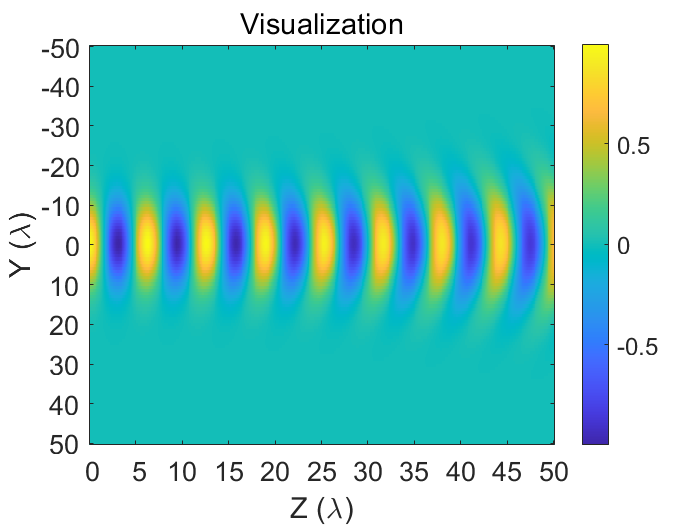

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%% Visualization %%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure();
imagesc(real(Y));
title('Visualization');
xlabel('Z (\lambda)');
ylabel('Y (\lambda)');
% Set X-axis tick labels.
xTicks = 0:5:50;  % Generate tick values from 0 to 100 with an interval of 10.
xTickLabels = cellstr(num2str(xTicks'));  % Convert tick values to a cell array of strings.
set(gca, 'XTick', linspace(1, 500, numel(xTicks)));  % Set X-axis tick positions.
set(gca, 'XTickLabel', xTickLabels);  % Set X-axis tick labels.
% Set Y-axis tick labels.
yTicks = linspace(-50, 50, 11);  % Generate 11 evenly spaced tick values within the range -50 to 50.
yTickLabels = cellstr(num2str(yTicks'));  % Convert tick values to a cell array of strings.
set(gca, 'YTick', linspace(1, 128, 11));  % Set Y-axis tick positions.
set(gca, 'YTickLabel', yTickLabels);  % Set Y-axis tick labels.
colorbar
set(gca,'FontSize',16)

## Part2: Wave propagating in free space

### Introduction to Gaussian beam

Gaussian beams are usually (and also in this article) considered in situations where the beam divergence is relatively small (i.e., the beam waist radius sufficiently large), so that the so-called *paraxial approximation* can be applied. This approximation allows the omission of the term with the second-order derivative in the propagation equation (as derived from Maxwell's equations), so that a first-order differential equation results. Within the paraxial approximation, a Gaussian beam propagating in free space (or in a homogeneous medium) remains Gaussian, except that of course its parameters evolve. For a monochromatic beam, propagating in the $z$ direction with the wavelength $\lambda$, the complex electric field amplitude (phasor) is


$$E(r, z)=E_0 \frac{w_0}{w(z)} \exp \left(-\frac{r^2}{w(z)^2}\right) \exp \left(i\left[k z-\arctan \frac{z}{z_{\mathrm{R}}}+\frac{k r^2}{2 R(z)}\right]\right)$$


with the peak amplitude $|E_0|$ and beam radius $\omega_0$ at the beam waist, the wavenumber $k=2\pi/\lambda$, the Rayleigh length $z_R$  (see below) and the radius of curvature $R(z)$ of the wavefronts.

Due to the basic phenomenon of diffraction, the beam radius cannot simply remain constant – it varies along the propagation direction. This can be described mathematically as,


$$w(z)=w_0 \sqrt{1+\left(z / z_{\mathrm{R}}\right)^2}$$


with the Rayleigh length


$$z_{\mathrm{R}}=\frac{\pi w_0^2}{\lambda}$$


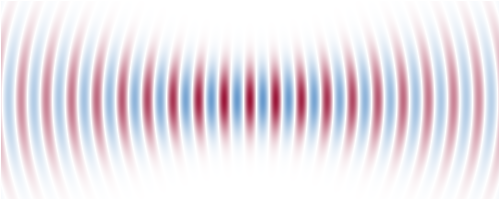

Fig02: Snapshot of the electric field distribution around the focus of a [Gaussian beam](https://www.rp-photonics.com/gaussian_beams.html). In this example, the beam radius is only slightly larger than the wavelength, and the beam divergence is strong. According to the equation above, the field pattern is moving from left to right.

### Propagation with Gaussian wave

Let's try to propagate a Gaussian wave in free space, and build up basic understanding about it. For simplify, we set amp for initial wave to A=1, and beam waist sigma=0.1.  

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%% Initial Conditions-1：Gaussian wave %%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

y=zeros(1,N);
A=1;sigma=0.1;

for i=1:N
    y(i)=A*exp(-(i-N/2)^2/N/N/sigma^2);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%% Propagation %%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Y=zeros(N,NUM); % Record WaveFunction in space

for i=1:NUM
    % Half step in real space
    y=y.*exp(-ii*V(i,:)*dz/2); 
    % One step in spectre space
    yf=fft(y);yf=yf.*LINEAR_FACTOR;y=ifft(yf);    
    % Half step in real space
    y=y.*exp(-ii*V(i,:)*dz/2);
    Y(:,i)=y; % Record
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%% Visualization %%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure();
imagesc(real(Y));
title('Visualization');
xlabel('Z (\lambda)');
ylabel('Y (\lambda)');
% Set X-axis tick labels.
xTicks = 0:5:50;  % Generate tick values from 0 to 100 with an interval of 10.
xTickLabels = cellstr(num2str(xTicks'));  % Convert tick values to a cell array of strings.
set(gca, 'XTick', linspace(1, 500, numel(xTicks)));  % Set X-axis tick positions.
set(gca, 'XTickLabel', xTickLabels);  % Set X-axis tick labels.
% Set Y-axis tick labels.
yTicks = linspace(-50, 50, 11);  % Generate 11 evenly spaced tick values within the range -50 to 50.
yTickLabels = cellstr(num2str(yTicks'));  % Convert tick values to a cell array of strings.
set(gca, 'YTick', linspace(1, 128, 11));  % Set Y-axis tick positions.
set(gca, 'YTickLabel', yTickLabels);  % Set Y-axis tick labels.
colorbar
set(gca,'FontSize',16)

### Propagation with Plane wave

In this part, we try to propagate a plane wave in free space,

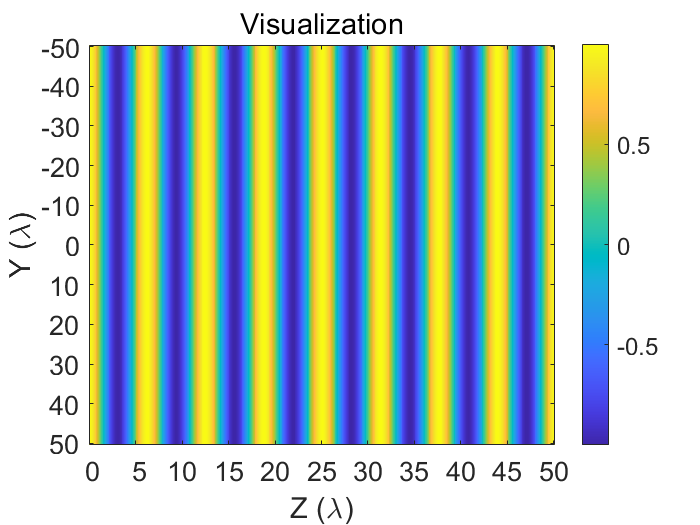

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%% Initial Conditions-2：plane wave %%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for i=1:N
    y(i)=1;
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%% Propagation %%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Y=zeros(N,NUM); % Record WaveFunction in space

for i=1:NUM
    % Half step in real space
    y=y.*exp(-ii*V(i,:)*dz/2); 
    % One step in spectre space
    yf=fft(y);yf=yf.*LINEAR_FACTOR;y=ifft(yf);    
    % Half step in real space
    y=y.*exp(-ii*V(i,:)*dz/2);
    Y(:,i)=y; % Record
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%% Visualization %%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure();
imagesc(real(Y));
title('Visualization');
xlabel('Z (\lambda)');
ylabel('Y (\lambda)');
% Set X-axis tick labels.
xTicks = 0:5:50;  % Generate tick values from 0 to 100 with an interval of 10.
xTickLabels = cellstr(num2str(xTicks'));  % Convert tick values to a cell array of strings.
set(gca, 'XTick', linspace(1, 500, numel(xTicks)));  % Set X-axis tick positions.
set(gca, 'XTickLabel', xTickLabels);  % Set X-axis tick labels.
% Set Y-axis tick labels.
yTicks = linspace(-50, 50, 11);  % Generate 11 evenly spaced tick values within the range -50 to 50.
yTickLabels = cellstr(num2str(yTicks'));  % Convert tick values to a cell array of strings.
set(gca, 'YTick', linspace(1, 128, 11));  % Set Y-axis tick positions.
set(gca, 'YTickLabel', yTickLabels);  % Set Y-axis tick labels.
colorbar
set(gca,'FontSize',16)

From the results, we can easily deduce that the real part of the wave has a period of 2*pi. By altering the potential (akin to the refractive index in optics), you can observe how this period changes accordingly. In the following example, when you set V to be 2 times larger, you will notice a halving of the period. Feel free to try it by clicking the buttun!

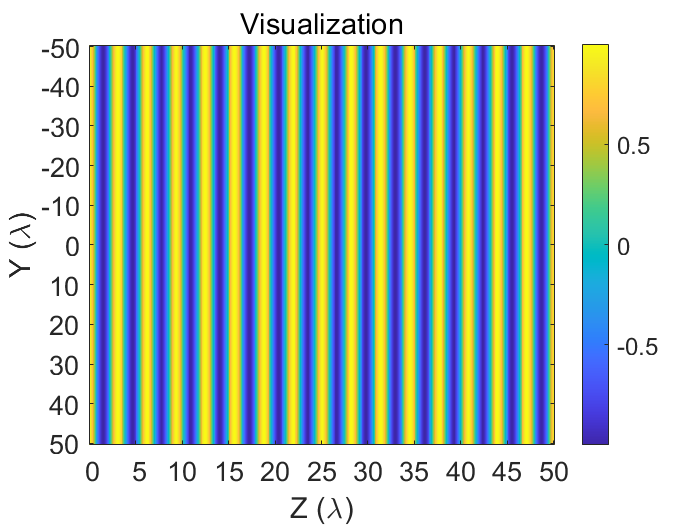

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%% Free space potential %%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

V=2*ones(NUM,N);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%% Initial Conditions-2：plane wave %%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for i=1:N
    y(i)=1;
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%% Propagation %%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Y=zeros(N,NUM); % Record WaveFunction in space

for i=1:NUM
    % Half step in real space
    y=y.*exp(-ii*V(i,:)*dz/2); 
    % One step in spectre space
    yf=fft(y);yf=yf.*LINEAR_FACTOR;y=ifft(yf);    
    % Half step in real space
    y=y.*exp(-ii*V(i,:)*dz/2);
    Y(:,i)=y; % Record
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%% Visualization %%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure();
imagesc(real(Y));
title('Visualization');
xlabel('Z (\lambda)');
ylabel('Y (\lambda)');
% Set X-axis tick labels.
xTicks = 0:5:50;  % Generate tick values from 0 to 100 with an interval of 10.
xTickLabels = cellstr(num2str(xTicks'));  % Convert tick values to a cell array of strings.
set(gca, 'XTick', linspace(1, 500, numel(xTicks)));  % Set X-axis tick positions.
set(gca, 'XTickLabel', xTickLabels);  % Set X-axis tick labels.
% Set Y-axis tick labels.
yTicks = linspace(-50, 50, 11);  % Generate 11 evenly spaced tick values within the range -50 to 50.
yTickLabels = cellstr(num2str(yTicks'));  % Convert tick values to a cell array of strings.
set(gca, 'YTick', linspace(1, 128, 11));  % Set Y-axis tick positions.
set(gca, 'YTickLabel', yTickLabels);  % Set Y-axis tick labels.
colorbar
set(gca,'FontSize',16)

## Summary

- Introduction to Split Operator Method

- Quick glance into SSFFT codes

- Basic property to Gaussian Beam

- Propagating a beam into a free space (air) by using different initial condition

## **Reference**

- **Split Operator Method: **[Leios's NoteBook](https://www.algorithm-archive.org/contents/split-operator_method/split-operator_method.html)

- **Gaussian Beam:** [RP-Photonics](https://www.rp-photonics.com/gaussian_beams.html)